clearvars
global options

Setting the range of settings and optimization parameters

Method          = ["sgdm","adam","rmsprop"];
initLearnRate   = [0.1 0.01 0.001];
MaxEpochs       = 150;  
MiniBatchSize   = [256 128];
Momentum        = 0.9;
conv            = 4;

Counter for experiment tracking

expNum = 1;

Loading training data through the matlab file responsible for it 

loadtrainingdata

setting the loops to run throught different options, if i just had one option i should comment the for loop for it and set the variable for it 

for lr = initLearnRate
    for mb = MiniBatchSize
        for mm = Method
            %for co = conv
            co = conv
            fprintf('\n=== Running Experiment %d ===\n', expNum);

clearing the variables that are more or less from previous expirments

            clearvars -except lr mb mm co conv ...
                options expNum ...
                trainImages valImages testImages ...
                trainLabels valLabels testLabels ...
                imageAugmenter trainDS valDS testDS ...
                initLearnRate MaxEpochs MiniBatchSize ...
                Momentum Method

calling the function that initialize the training options to loop through it

            createTrainingOptions(mm, lr,15, MaxEpochs, mb, valDS,50,Momentum,1)

selecting which set of layers will be applied to the network

            switch co
                case 2
                    conv2layers
                case 3
                    conv3layers
                case 4
                    conv4layers
            end

running the netweork 

co = 4


=== Running Experiment 1 ===


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.1000
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 256
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              ValidationPatience: 25
             ObjectiveMetricName: 


=== Running Training 1 ===

=== Done Training 1 ===


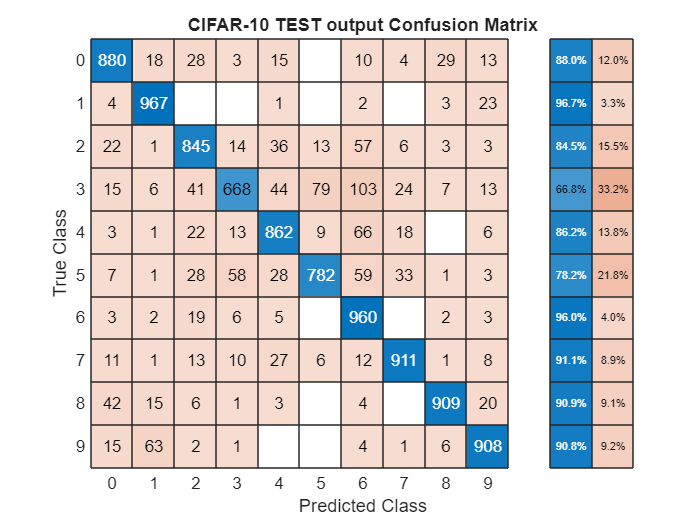

Overall Accuracy (from CM): 86.92%


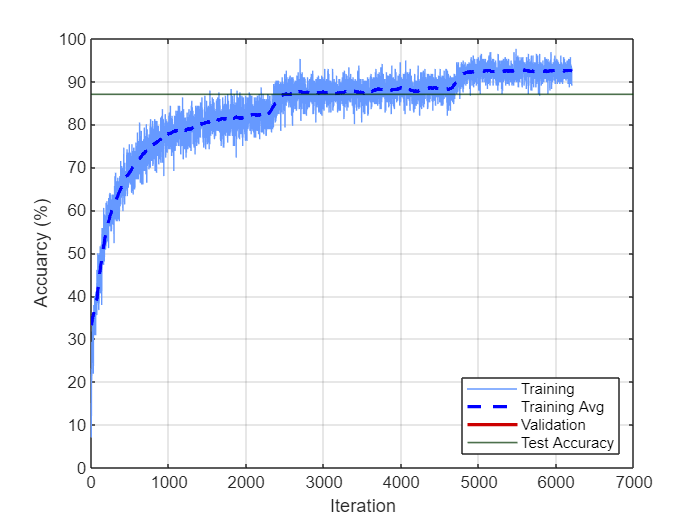

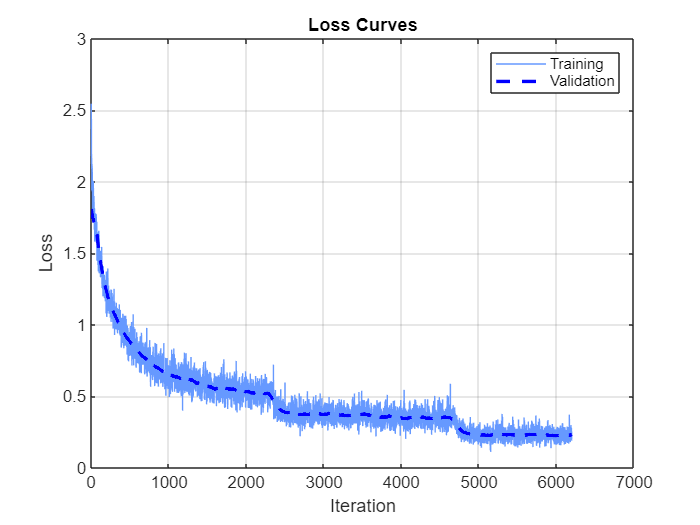

co = 4


=== Running Experiment 2 ===


ans =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.1000
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 256
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             Validatio


=== Running Training 2 ===

=== Done Training 2 ===


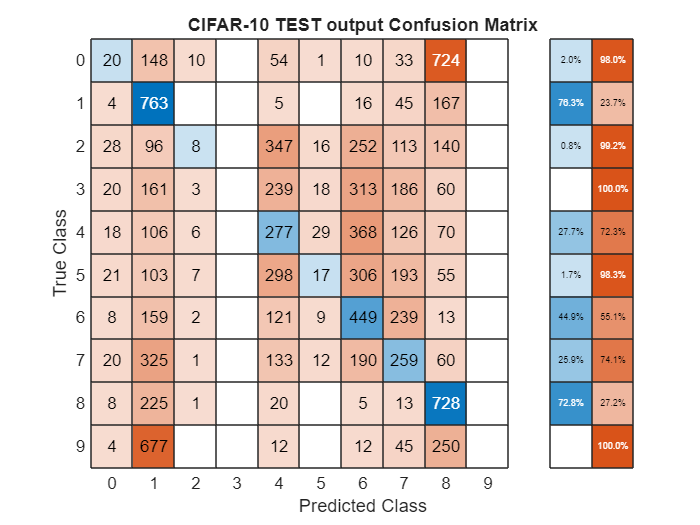

Overall Accuracy (from CM): 25.21%


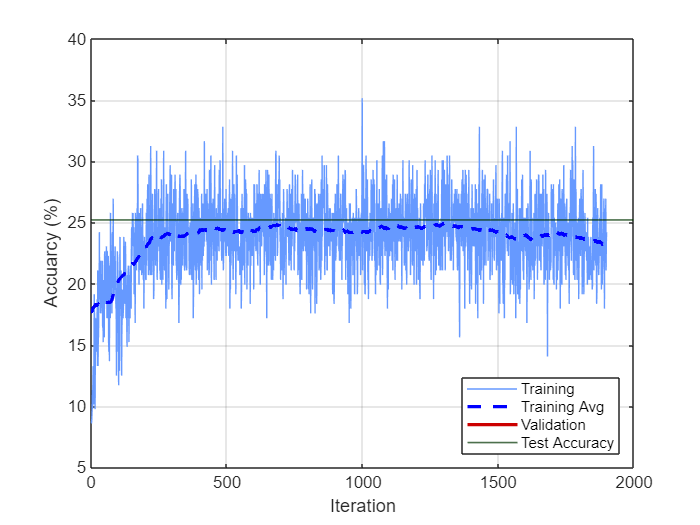

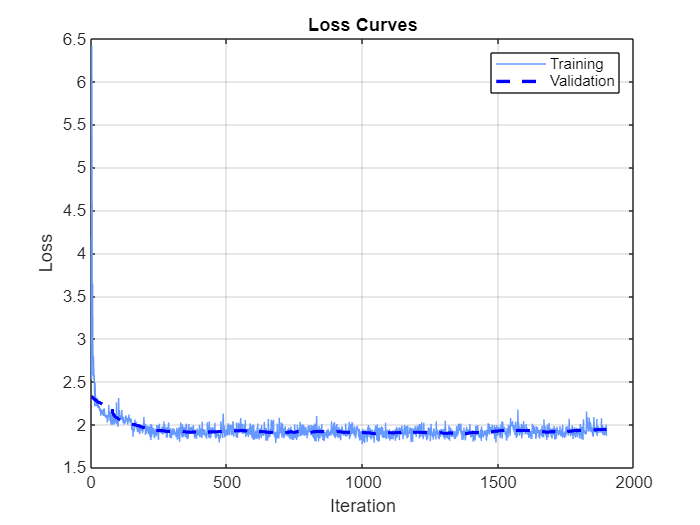

co = 4


=== Running Experiment 3 ===


ans =   TrainingOptionsRMSProp with properties:

      SquaredGradientDecayFactor: 0.9000
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.1000
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 256
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              Valida


=== Running Training 3 ===

=== Done Training 3 ===


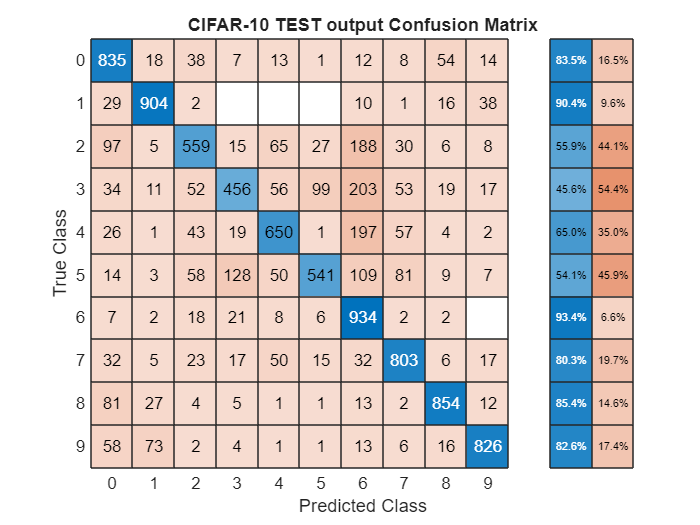

Overall Accuracy (from CM): 73.62%


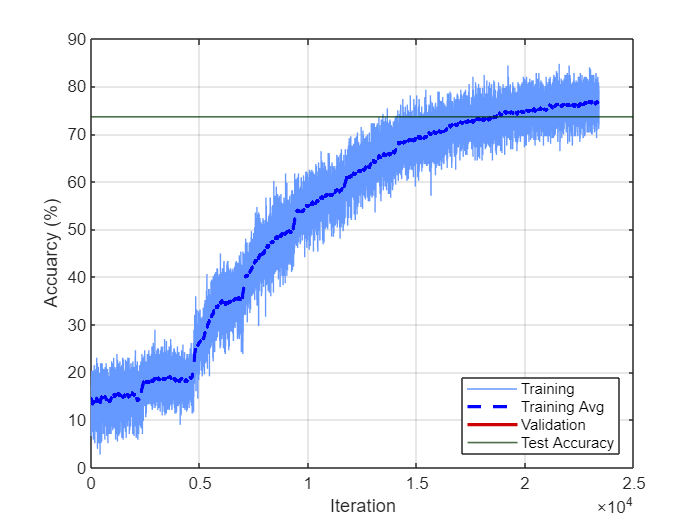

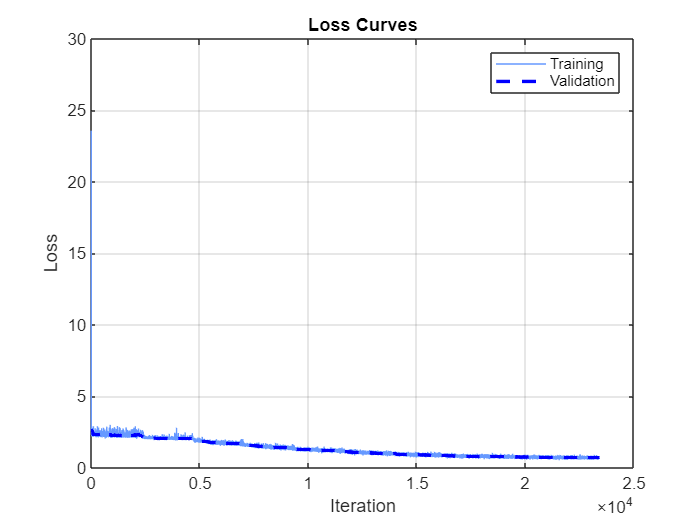

co = 4


=== Running Experiment 4 ===


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.1000
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 128
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              ValidationPatience: 25
             ObjectiveMetricName: 


=== Running Training 4 ===

=== Done Training 4 ===


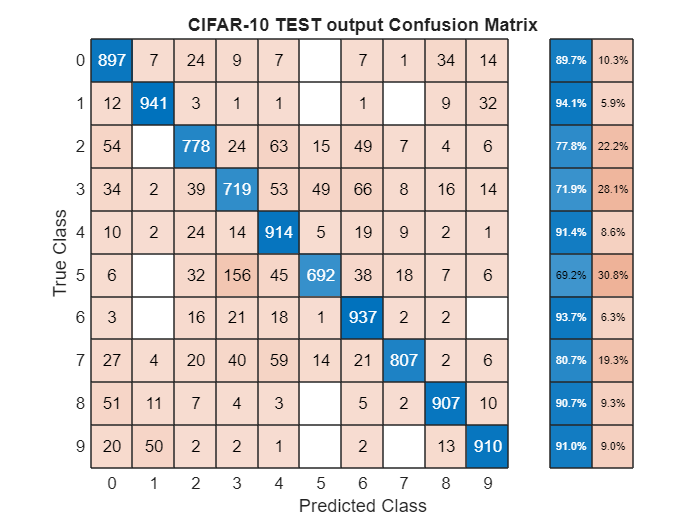

Overall Accuracy (from CM): 85.02%


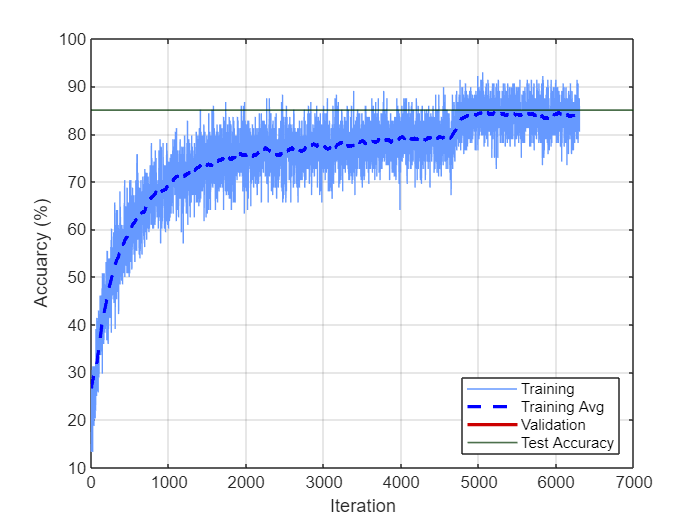

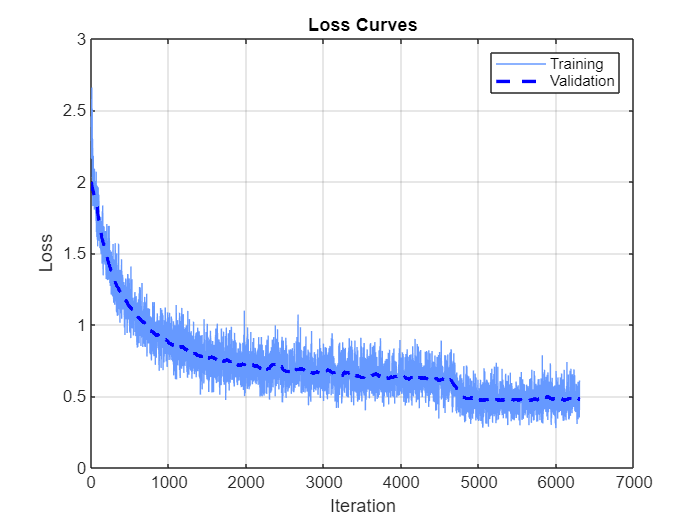

co = 4


=== Running Experiment 5 ===


ans =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.1000
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 128
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             Validatio


=== Running Training 5 ===

=== Done Training 5 ===


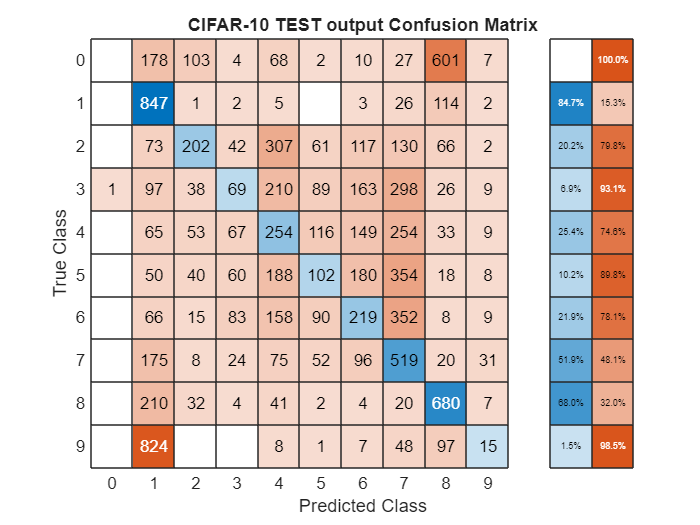

Overall Accuracy (from CM): 29.07%


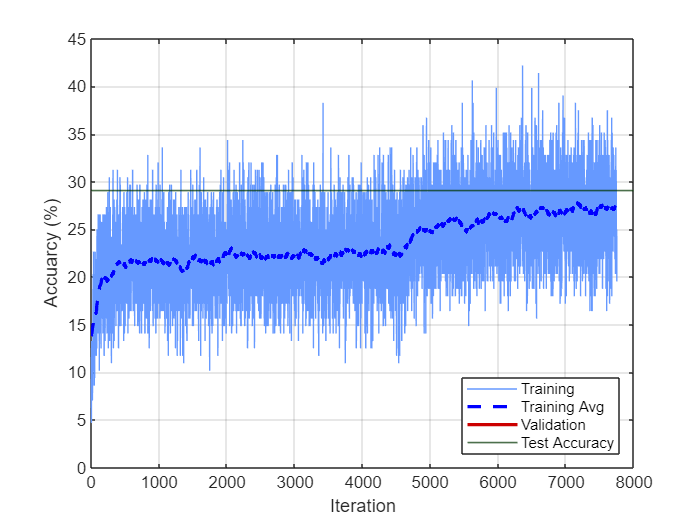

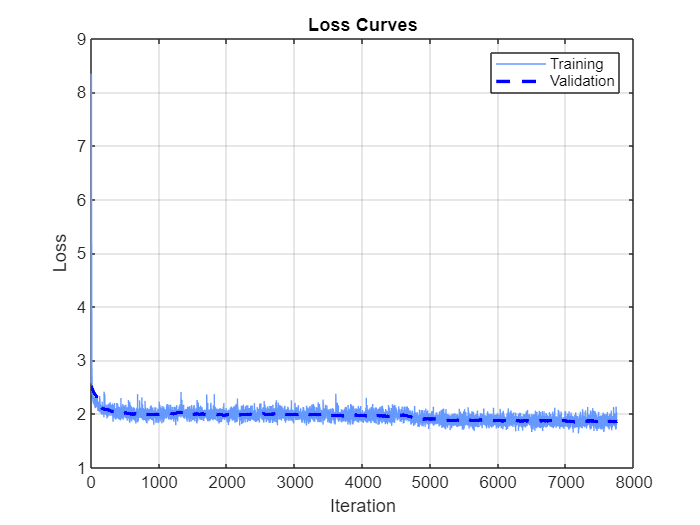

co = 4


=== Running Experiment 6 ===


ans =   TrainingOptionsRMSProp with properties:

      SquaredGradientDecayFactor: 0.9000
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.1000
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 128
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              Valida


=== Running Training 6 ===

=== Done Training 6 ===


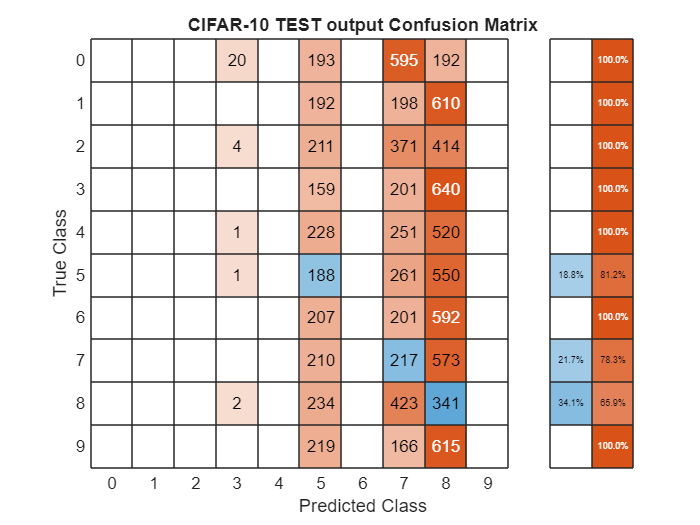

Overall Accuracy (from CM): 7.46%


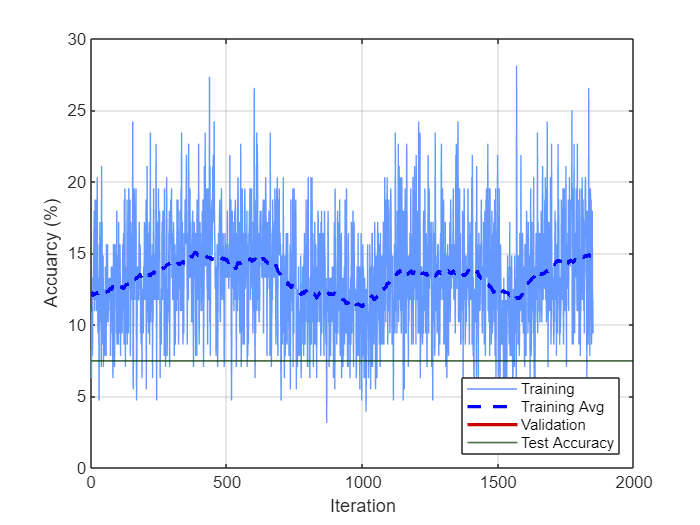

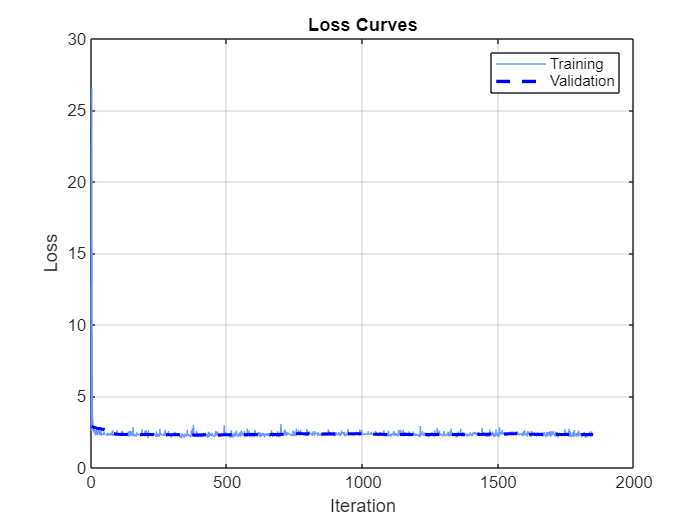

co = 4


=== Running Experiment 7 ===


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.1000
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 64
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              ValidationPatience: 25
             ObjectiveMetricName: '


=== Running Training 7 ===

=== Done Training 7 ===


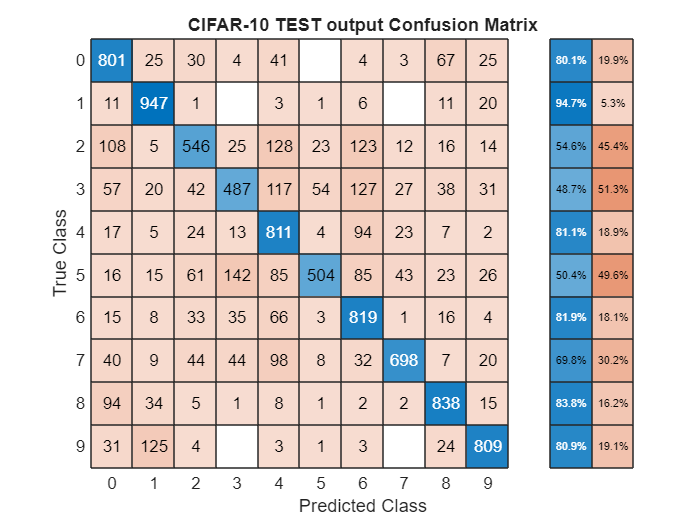

Overall Accuracy (from CM): 72.6%


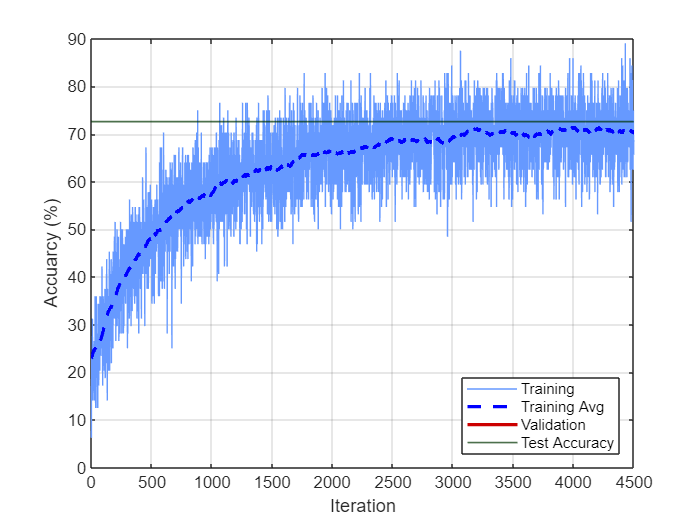

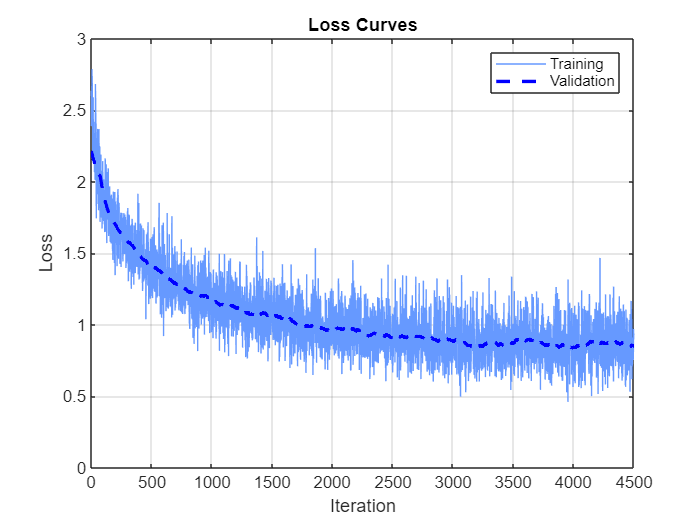

co = 4


=== Running Experiment 8 ===


ans =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.1000
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 64
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             Validation


=== Running Training 8 ===

=== Done Training 8 ===


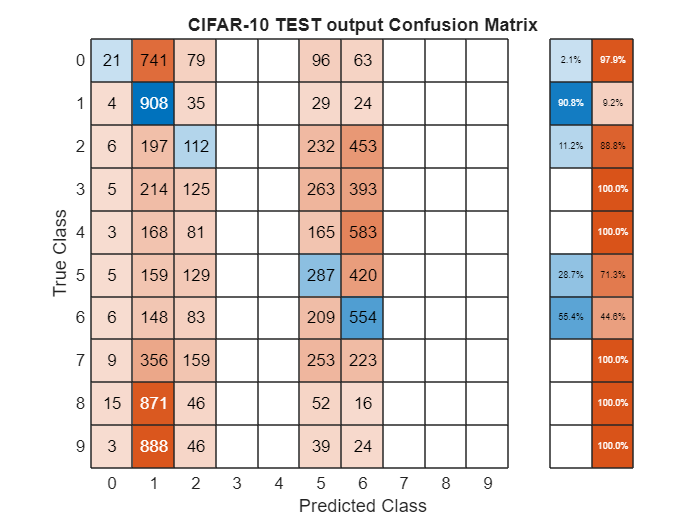

Overall Accuracy (from CM): 18.82%


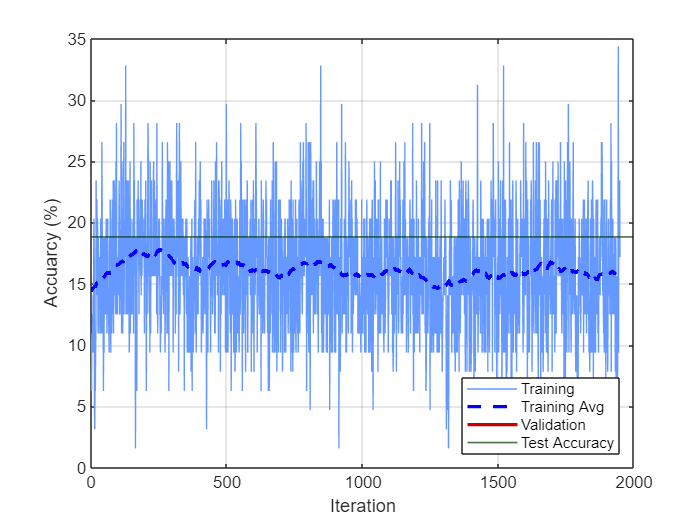

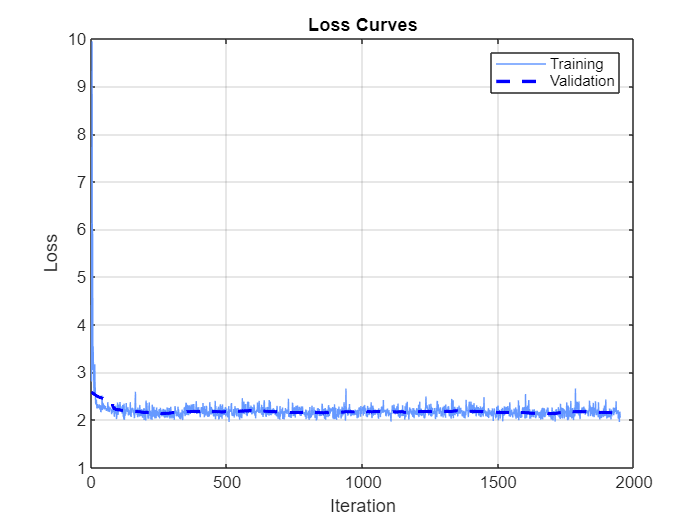

co = 4


=== Running Experiment 9 ===


ans =   TrainingOptionsRMSProp with properties:

      SquaredGradientDecayFactor: 0.9000
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.1000
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 64
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              Validat


=== Running Training 9 ===

=== Done Training 9 ===


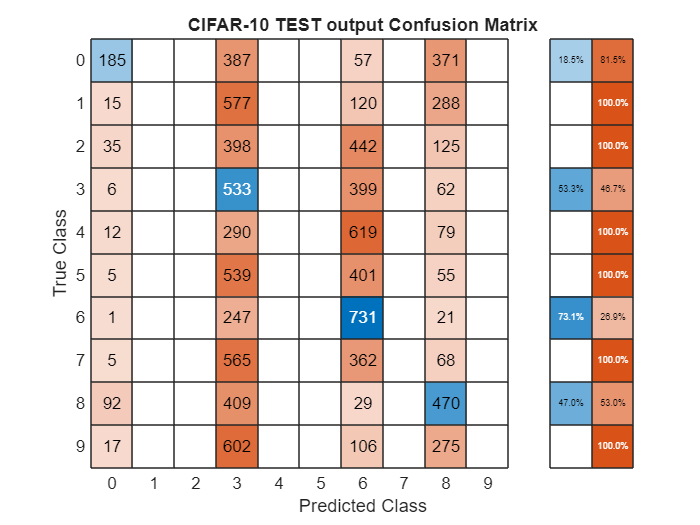

Overall Accuracy (from CM): 19.19%


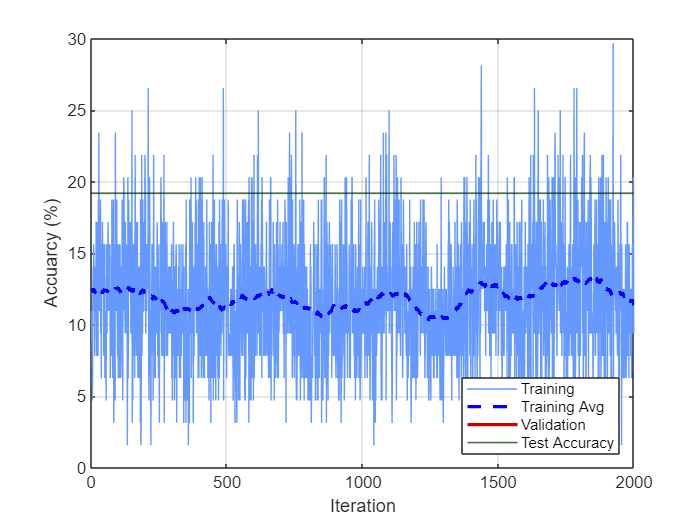

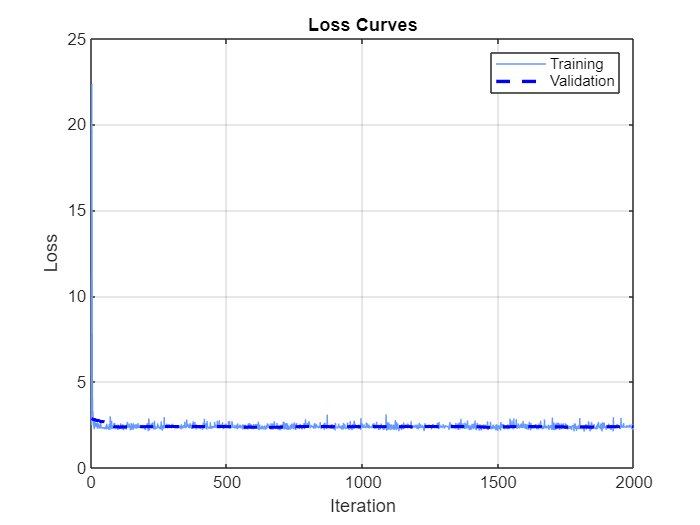

co = 4


=== Running Experiment 10 ===


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.0100
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 256
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              ValidationPatience: 25
             ObjectiveMetricName: 


=== Running Training 10 ===

=== Done Training 10 ===


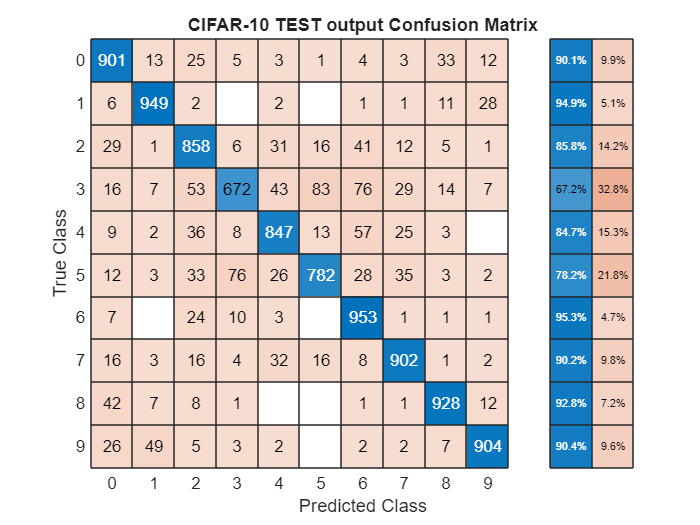

Overall Accuracy (from CM): 86.96%


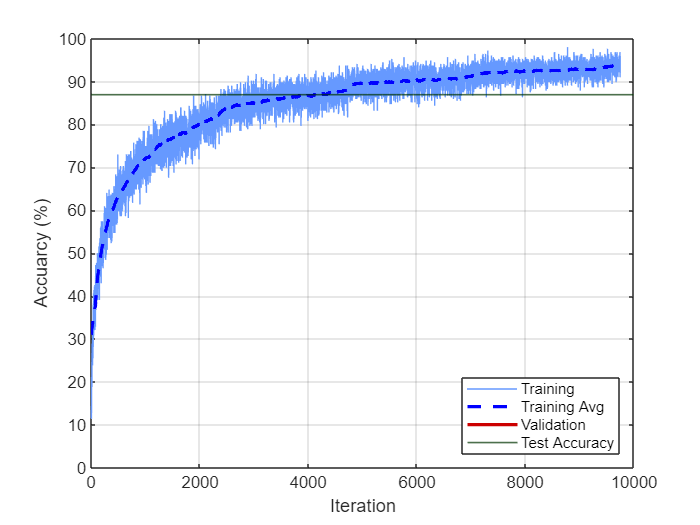

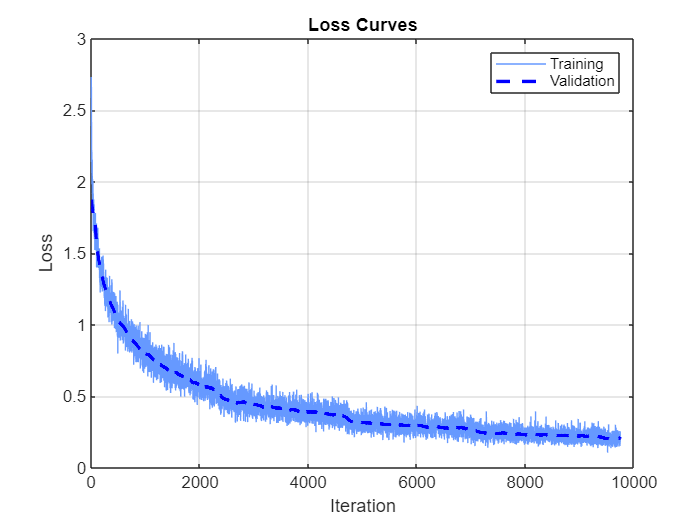

co = 4


=== Running Experiment 11 ===


ans =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.0100
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 256
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             Validatio


=== Running Training 11 ===

=== Done Training 11 ===


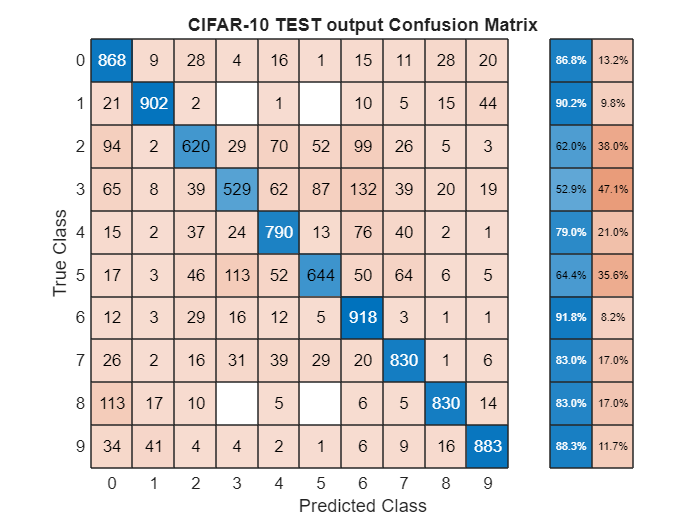

Overall Accuracy (from CM): 78.14%


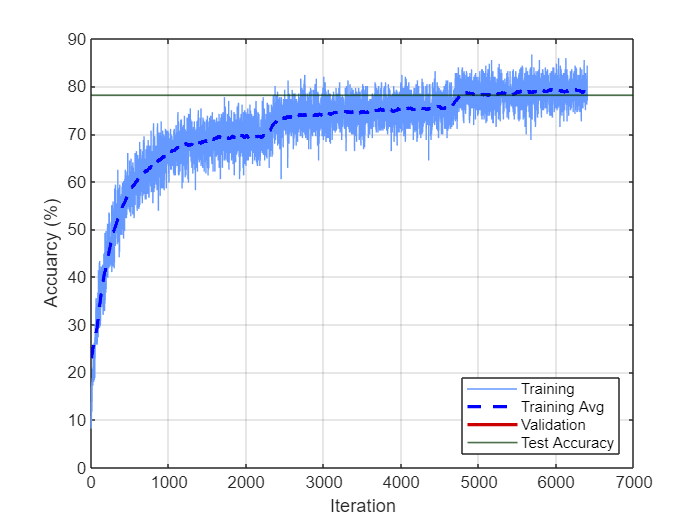

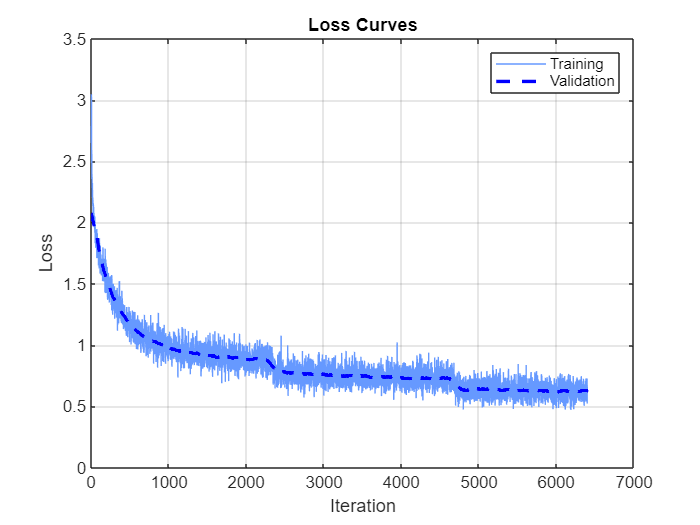

co = 4


=== Running Experiment 12 ===


ans =   TrainingOptionsRMSProp with properties:

      SquaredGradientDecayFactor: 0.9000
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.0100
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 256
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              Valida


=== Running Training 12 ===

=== Done Training 12 ===


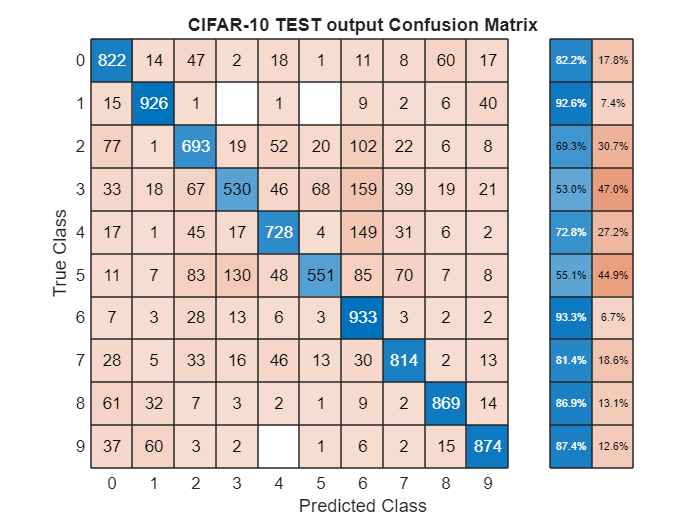

Overall Accuracy (from CM): 77.4%


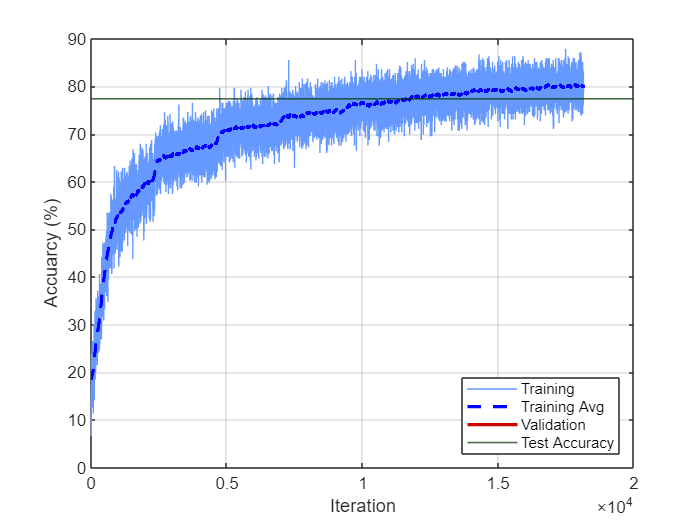

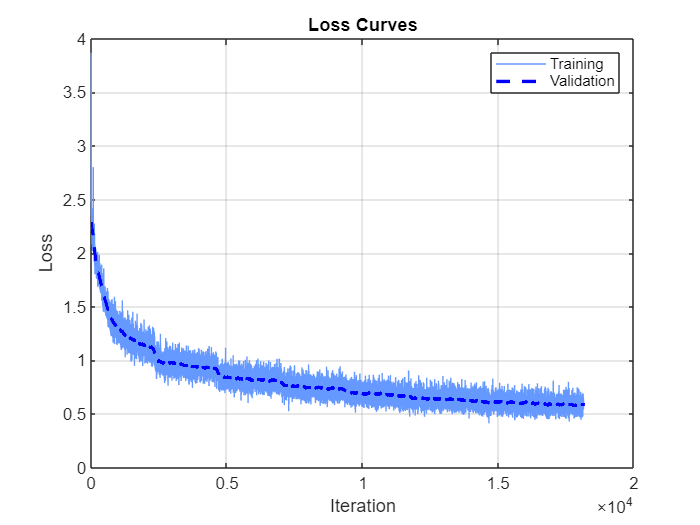

co = 4


=== Running Experiment 13 ===


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.0100
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 128
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              ValidationPatience: 25
             ObjectiveMetricName: 


=== Running Training 13 ===

=== Done Training 13 ===


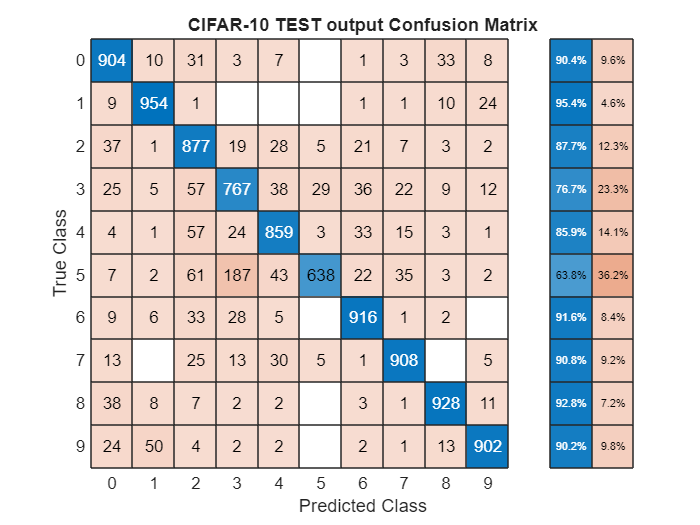

Overall Accuracy (from CM): 86.53%


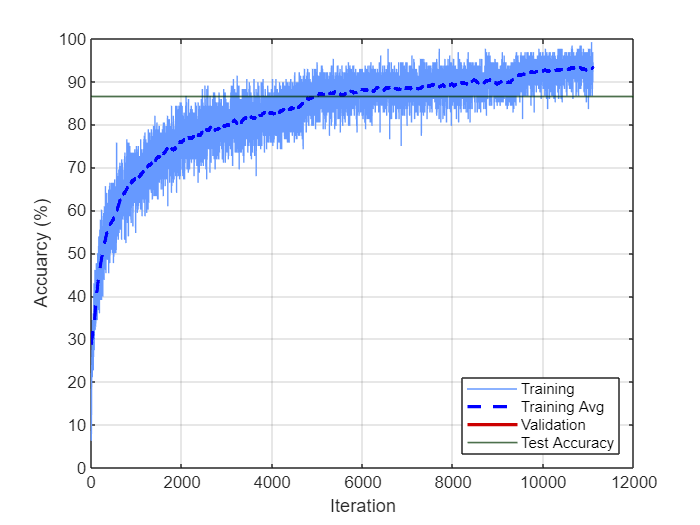

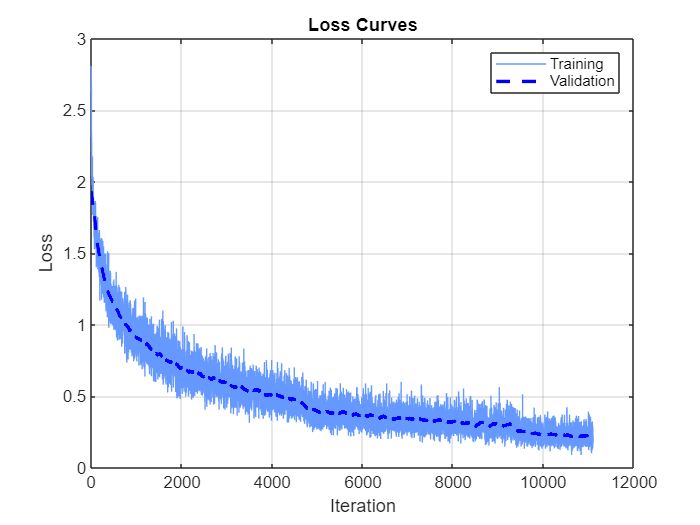

co = 4


=== Running Experiment 14 ===


ans =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.0100
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 128
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             Validatio


=== Running Training 14 ===

=== Done Training 14 ===


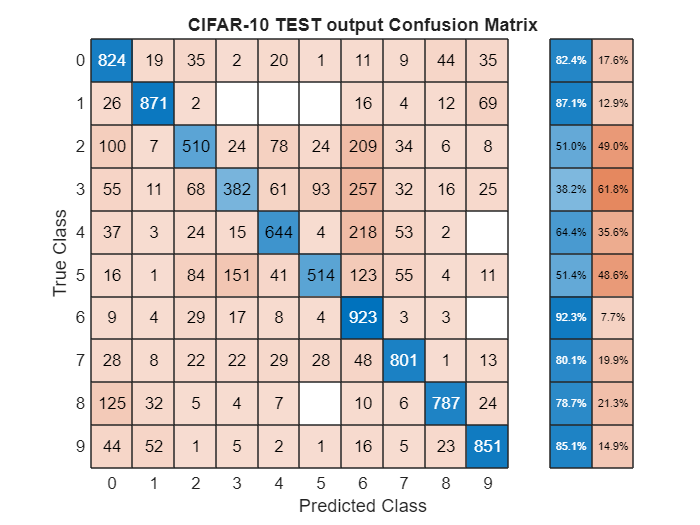

Overall Accuracy (from CM): 71.07%


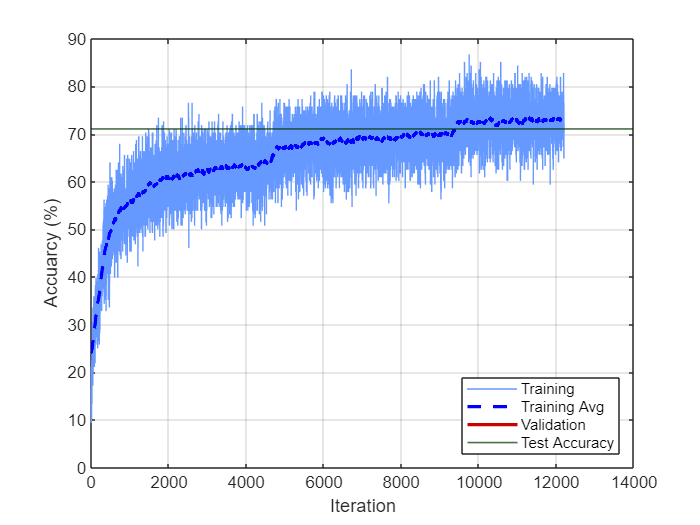

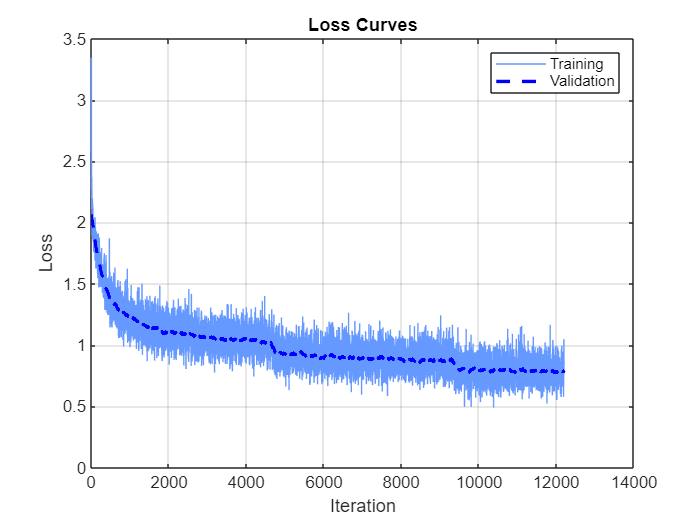

co = 4


=== Running Experiment 15 ===


ans =   TrainingOptionsRMSProp with properties:

      SquaredGradientDecayFactor: 0.9000
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.0100
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 128
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              Valida


=== Running Training 15 ===

=== Done Training 15 ===


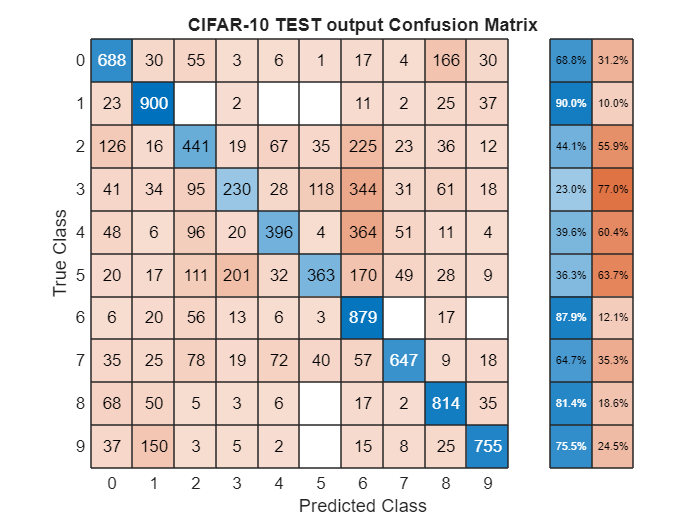

Overall Accuracy (from CM): 61.13%


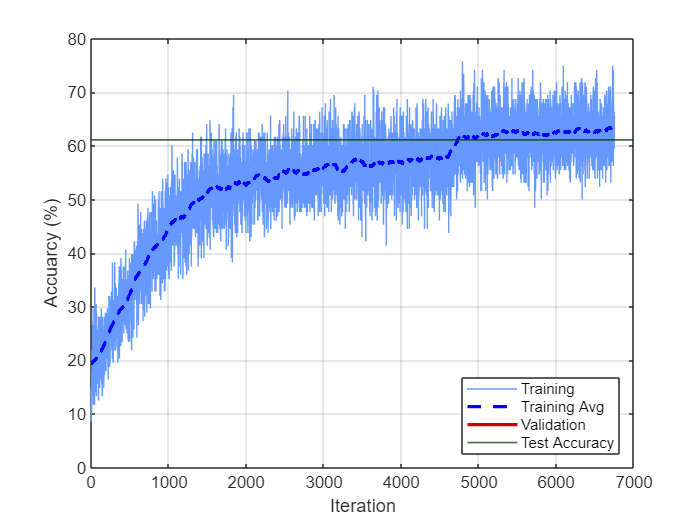

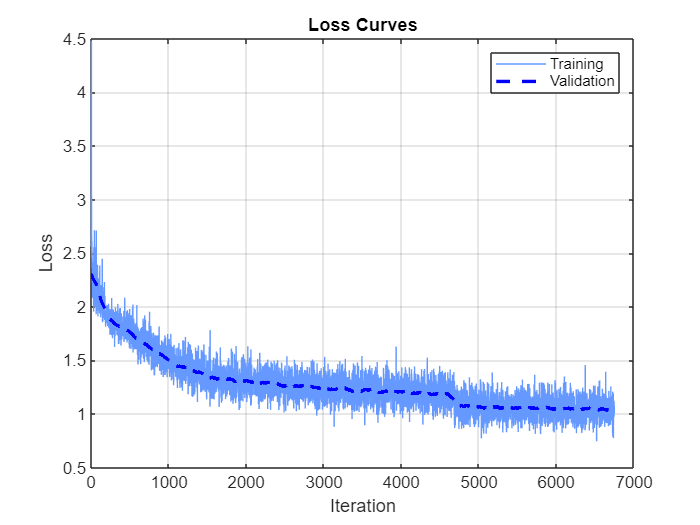

co = 4


=== Running Experiment 16 ===


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.0100
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 64
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              ValidationPatience: 25
             ObjectiveMetricName: '


=== Running Training 16 ===

=== Done Training 16 ===


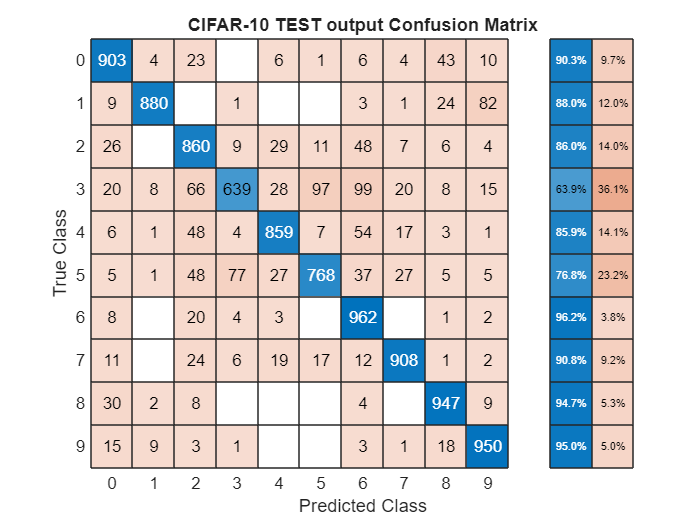

Overall Accuracy (from CM): 86.76%


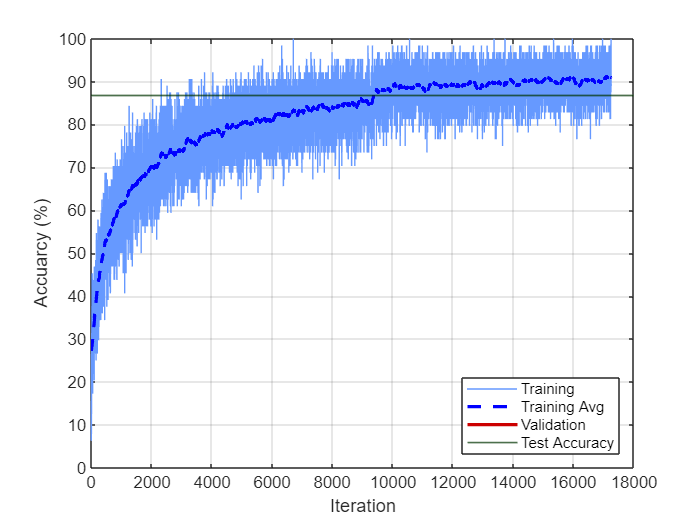

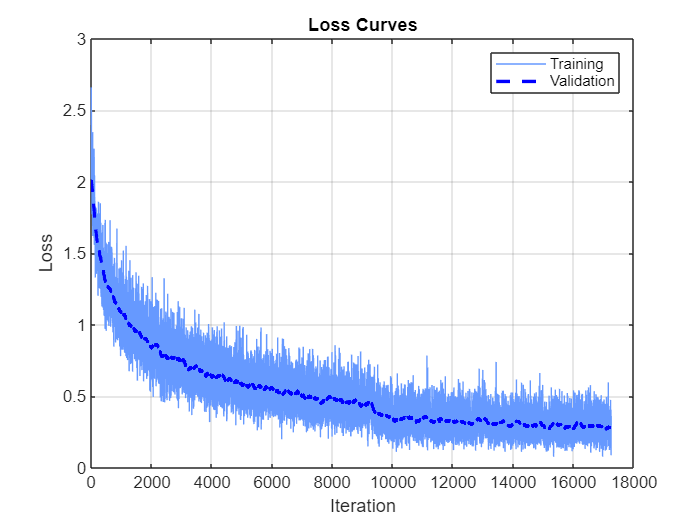

co = 4


=== Running Experiment 17 ===


ans =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.0100
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 64
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             Validation


=== Running Training 17 ===

=== Done Training 17 ===


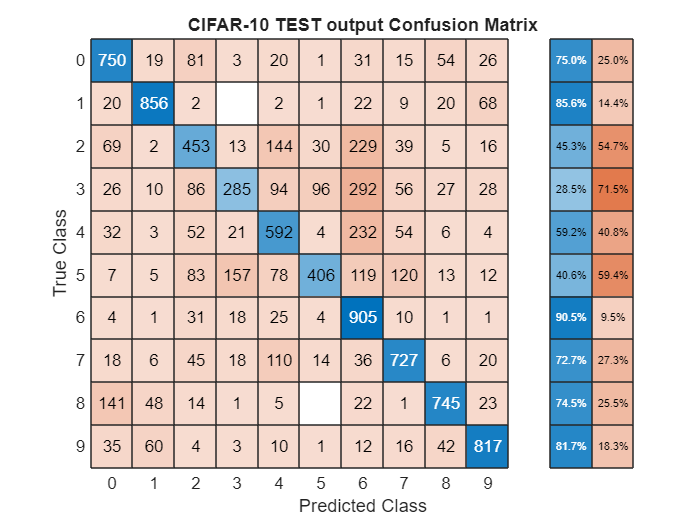

Overall Accuracy (from CM): 65.36%


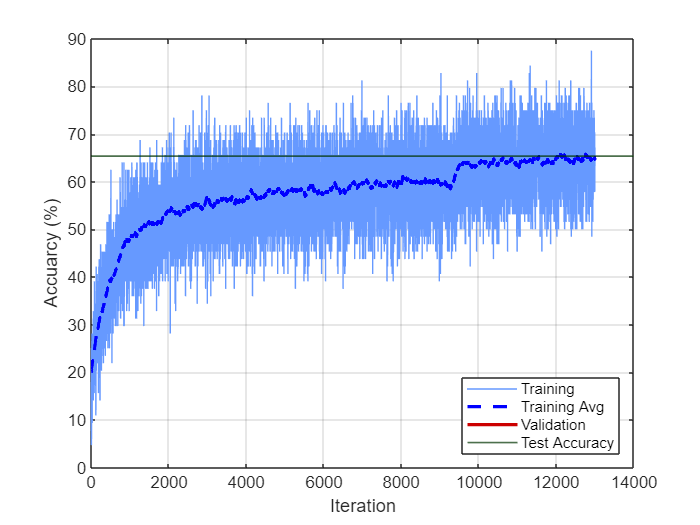

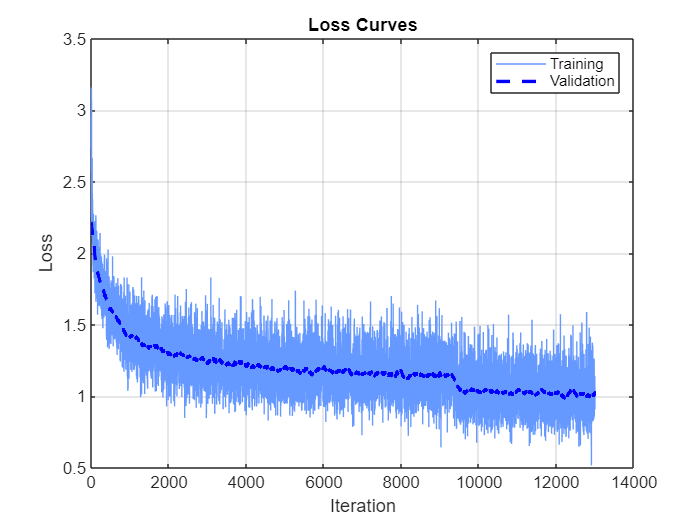

co = 4


=== Running Experiment 18 ===


ans =   TrainingOptionsRMSProp with properties:

      SquaredGradientDecayFactor: 0.9000
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.0100
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 64
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              Validat


=== Running Training 18 ===

=== Done Training 18 ===


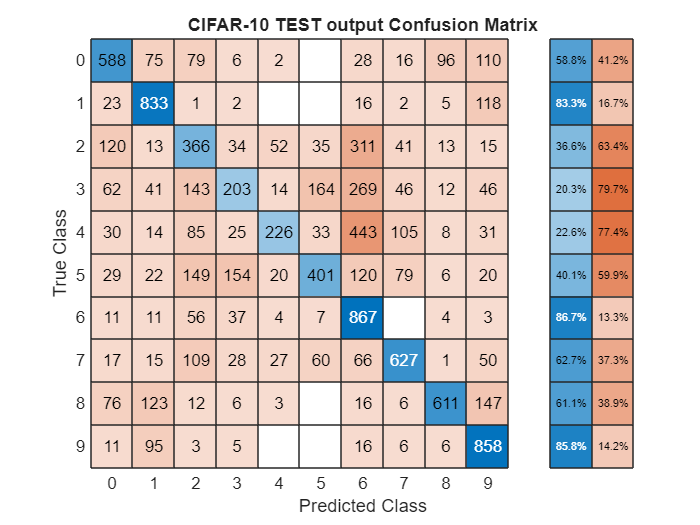

Overall Accuracy (from CM): 55.8%


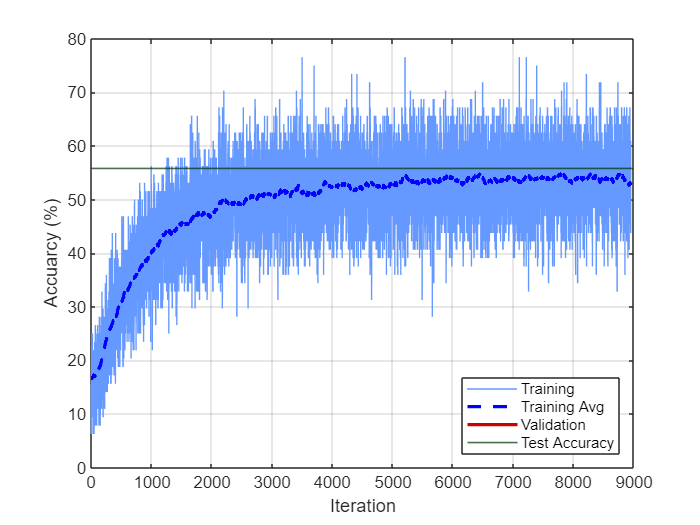

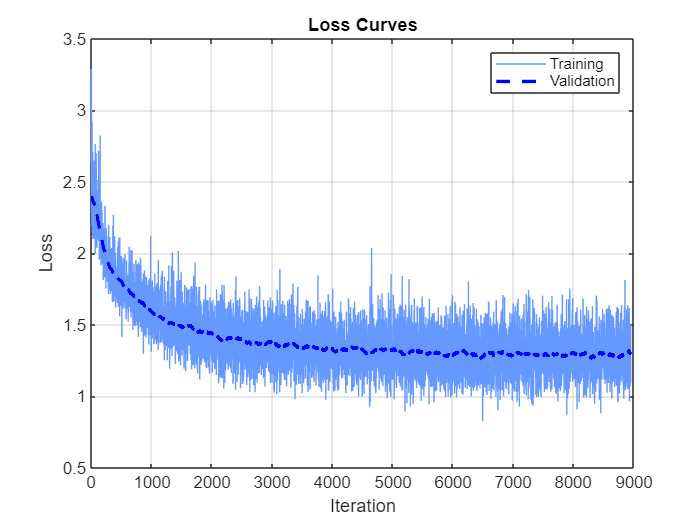

co = 4


=== Running Experiment 19 ===


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 256
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              ValidationPatience: 25
             ObjectiveMetricNa


=== Running Training 19 ===

=== Done Training 19 ===


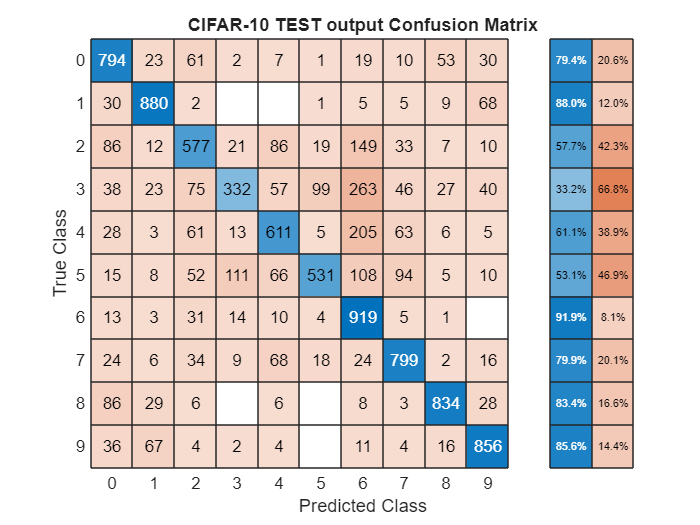

Overall Accuracy (from CM): 71.33%


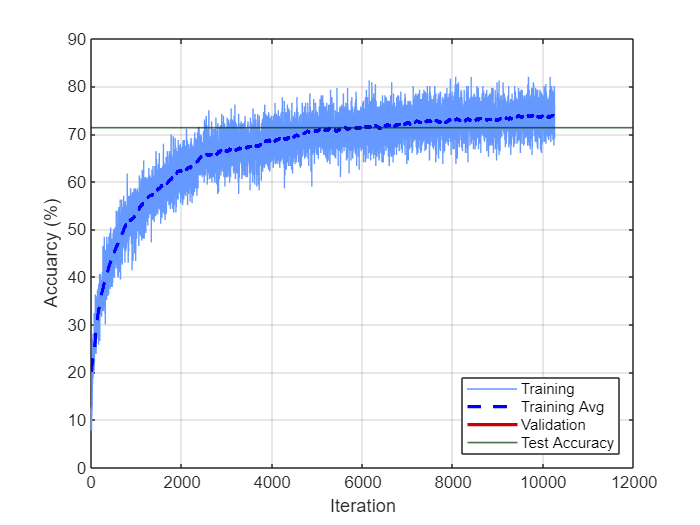

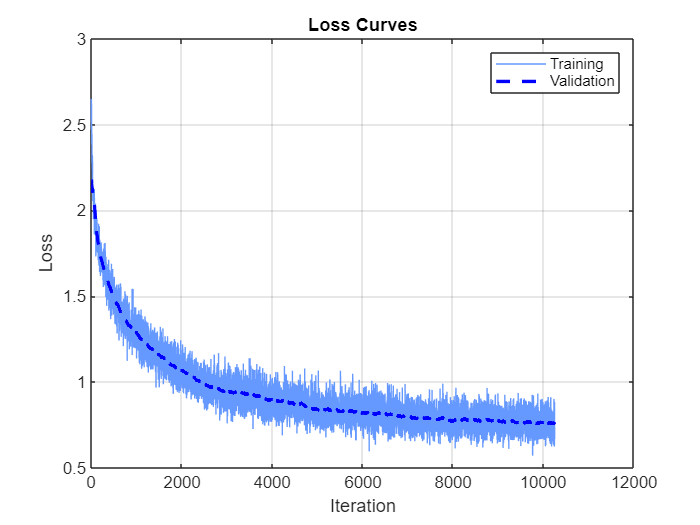

co = 4


=== Running Experiment 20 ===


ans =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 256
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             Valid


=== Running Training 20 ===

=== Done Training 20 ===


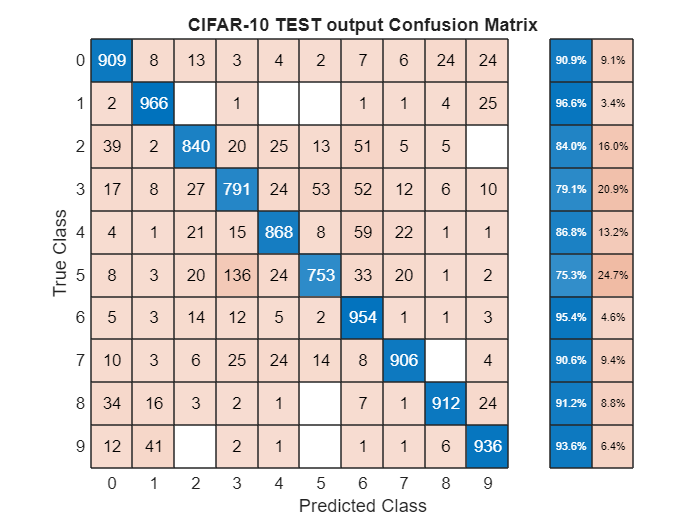

Overall Accuracy (from CM): 88.35%


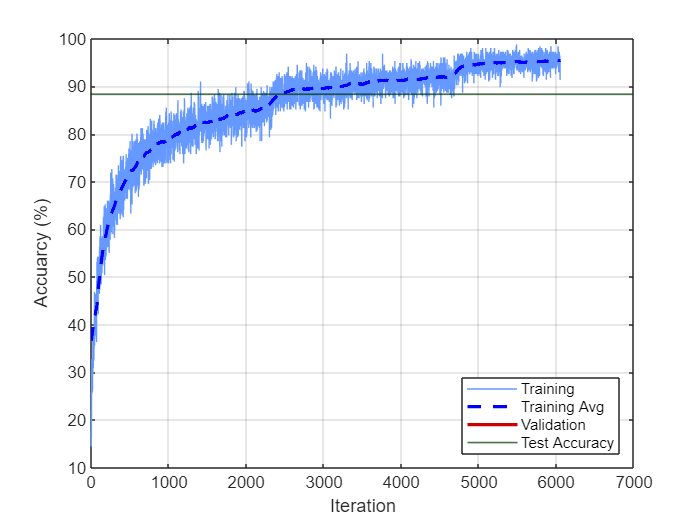

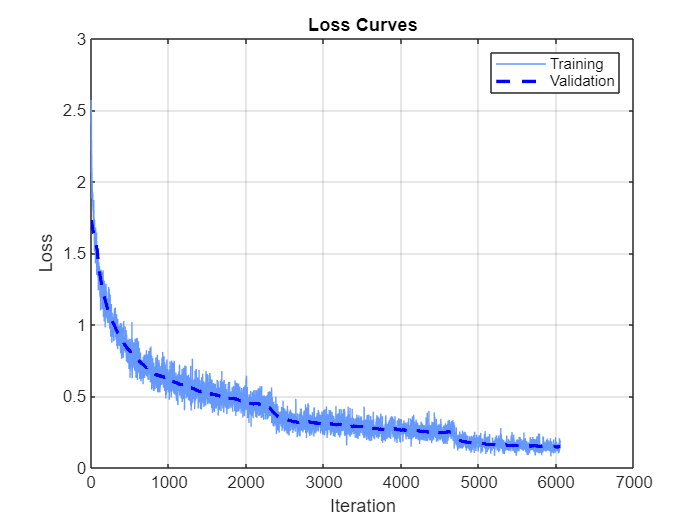

co = 4


=== Running Experiment 21 ===


ans =   TrainingOptionsRMSProp with properties:

      SquaredGradientDecayFactor: 0.9000
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 256
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              Va


=== Running Training 21 ===

=== Done Training 21 ===


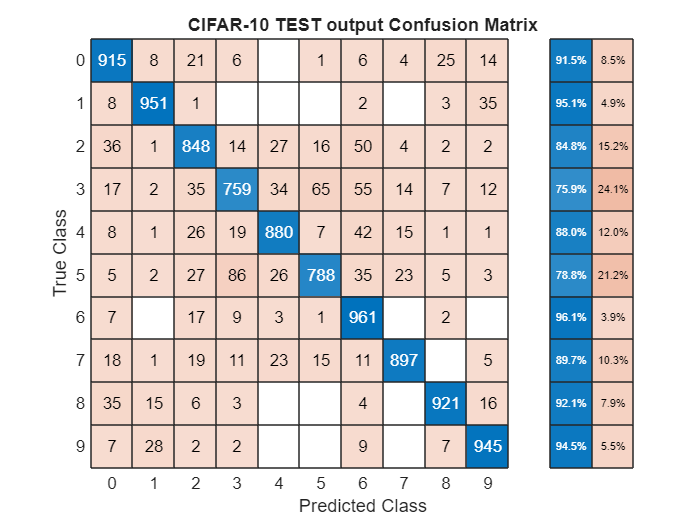

Overall Accuracy (from CM): 88.65%


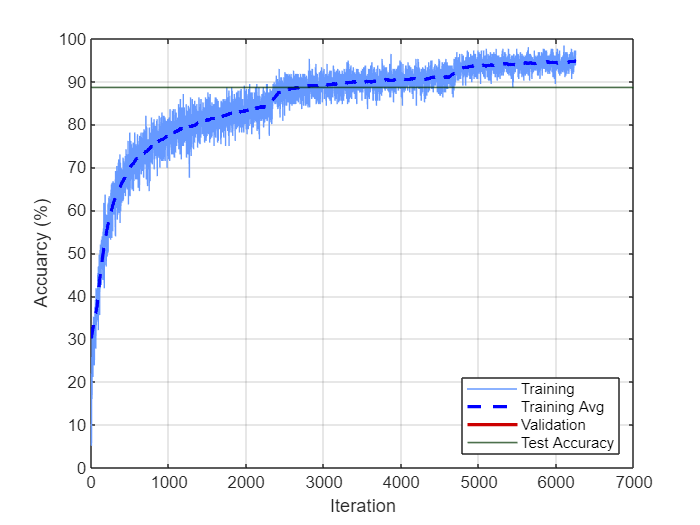

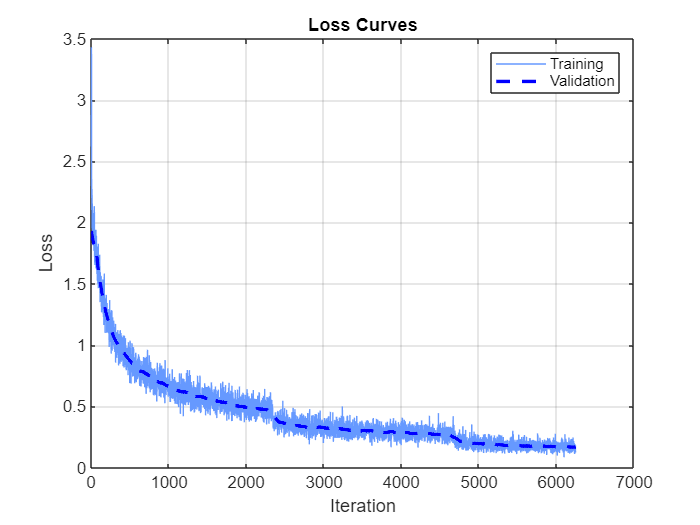

co = 4


=== Running Experiment 22 ===


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 128
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              ValidationPatience: 25
             ObjectiveMetricNa


=== Running Training 22 ===

=== Done Training 22 ===


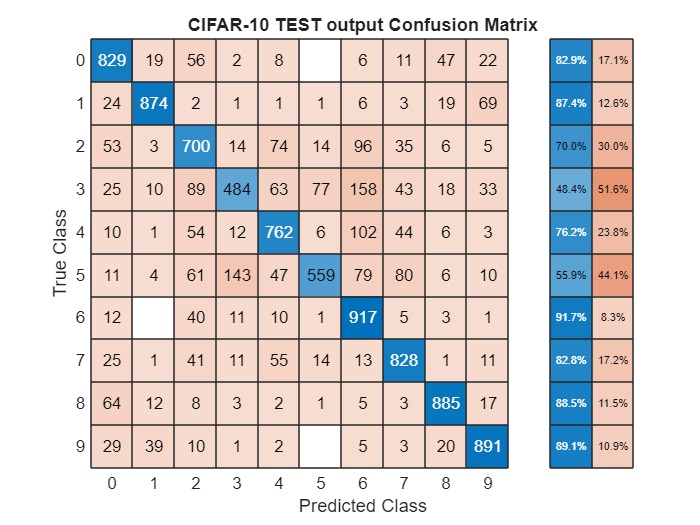

Overall Accuracy (from CM): 77.29%


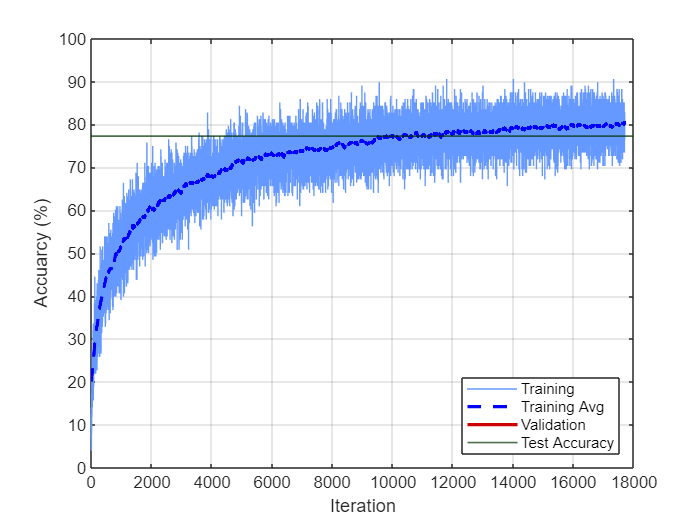

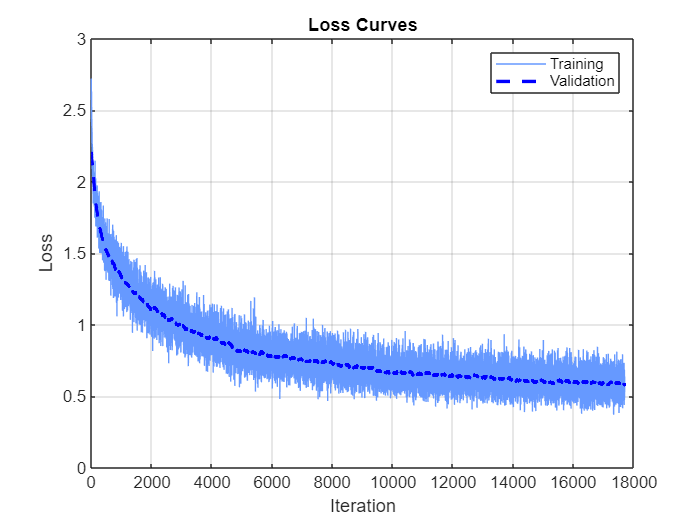

co = 4


=== Running Experiment 23 ===


ans =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 128
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             Valid


=== Running Training 23 ===

=== Done Training 23 ===


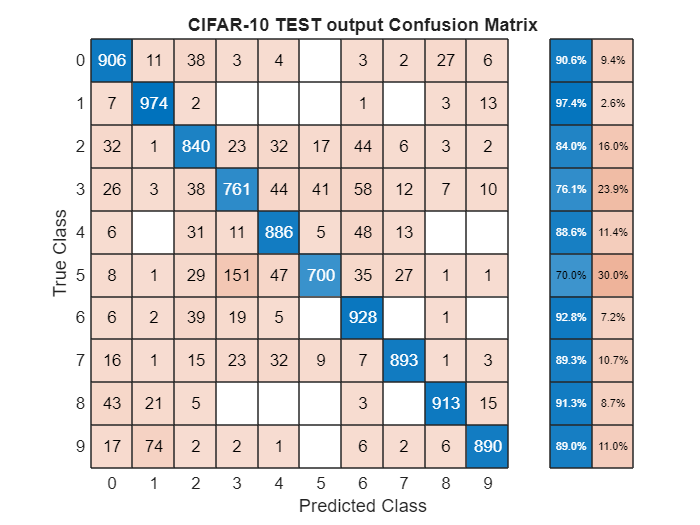

Overall Accuracy (from CM): 86.91%


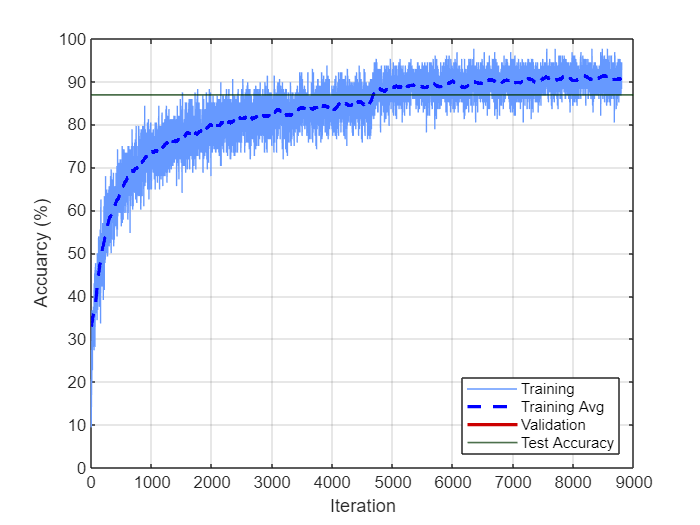

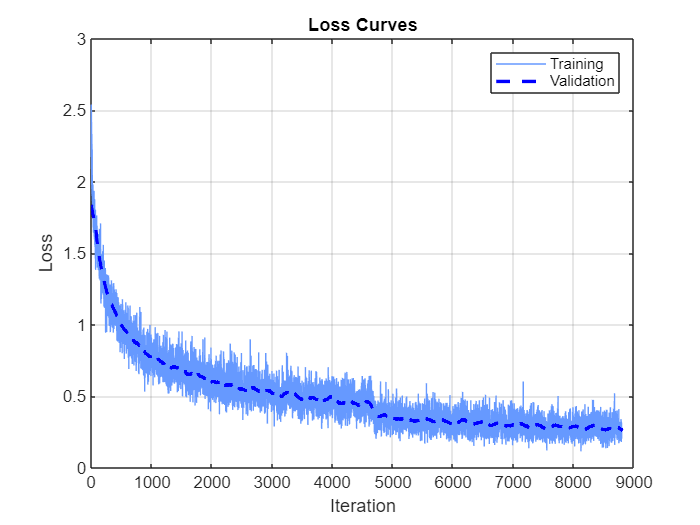

co = 4


=== Running Experiment 24 ===


ans =   TrainingOptionsRMSProp with properties:

      SquaredGradientDecayFactor: 0.9000
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 128
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              Va


=== Running Training 24 ===

=== Done Training 24 ===


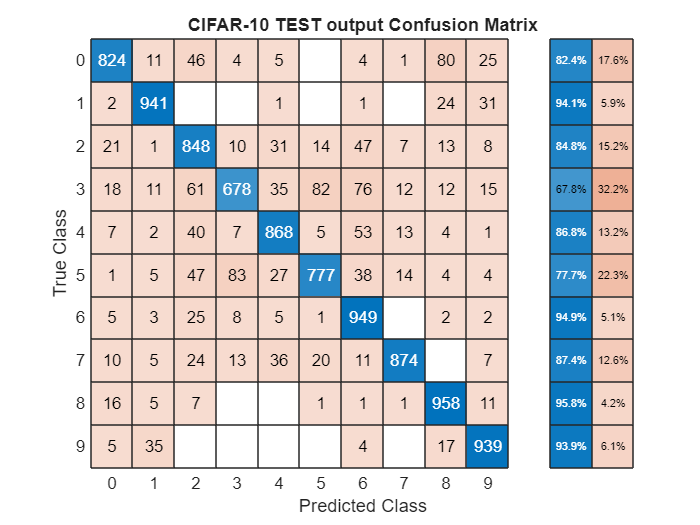

Overall Accuracy (from CM): 86.56%


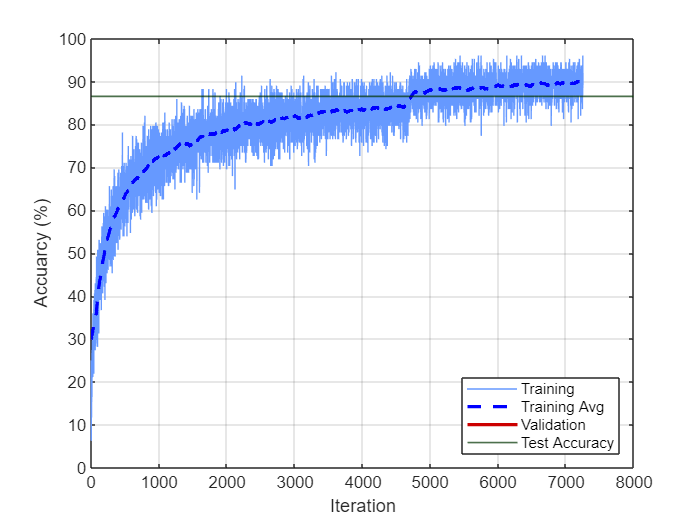

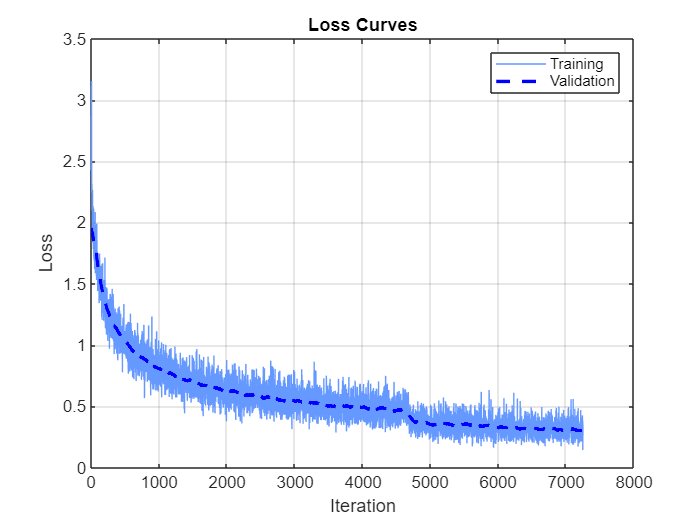

co = 4


=== Running Experiment 25 ===


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 64
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              ValidationPatience: 25
             ObjectiveMetricNam


=== Running Training 25 ===

=== Done Training 25 ===


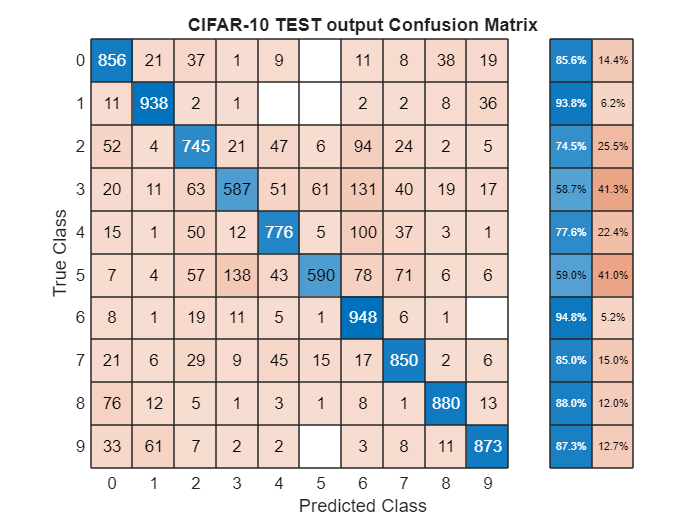

Overall Accuracy (from CM): 80.43%


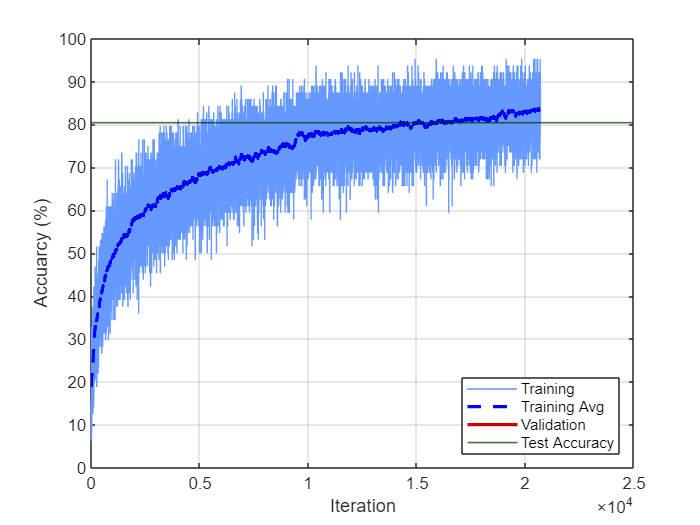

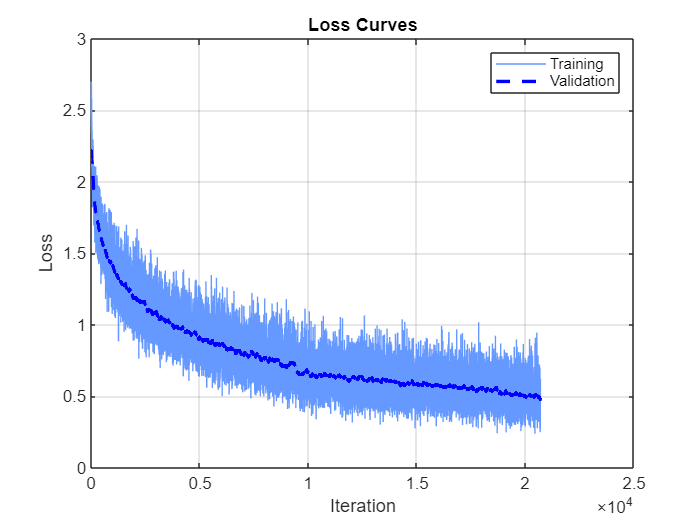

co = 4


=== Running Experiment 26 ===


ans =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 64
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             Valida


=== Running Training 26 ===

=== Done Training 26 ===


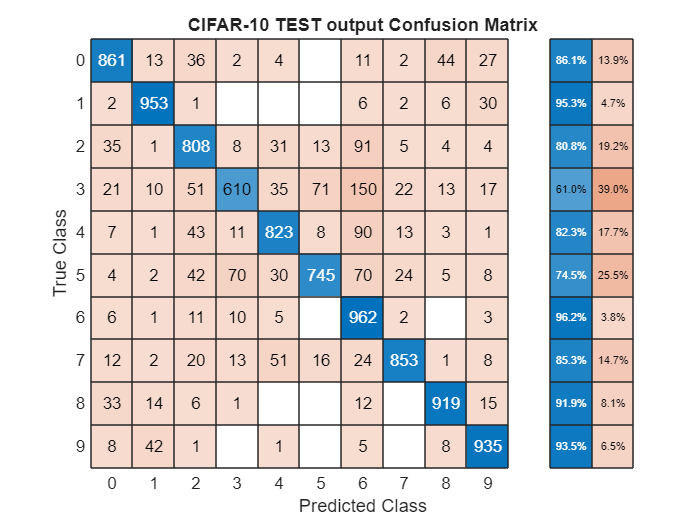

Overall Accuracy (from CM): 84.69%


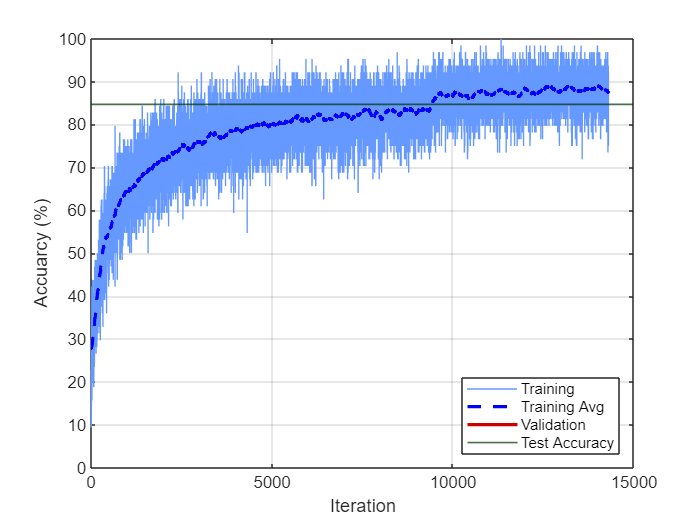

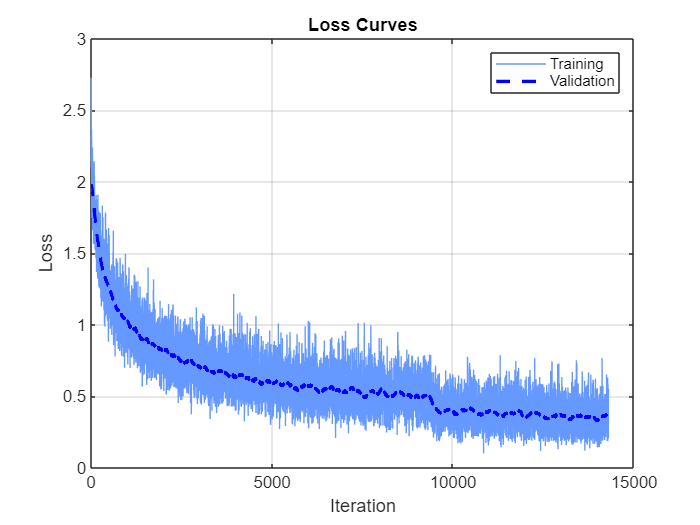

co = 4


=== Running Experiment 27 ===


ans =   TrainingOptionsRMSProp with properties:

      SquaredGradientDecayFactor: 0.9000
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.5000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 64
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              Val


=== Running Training 27 ===


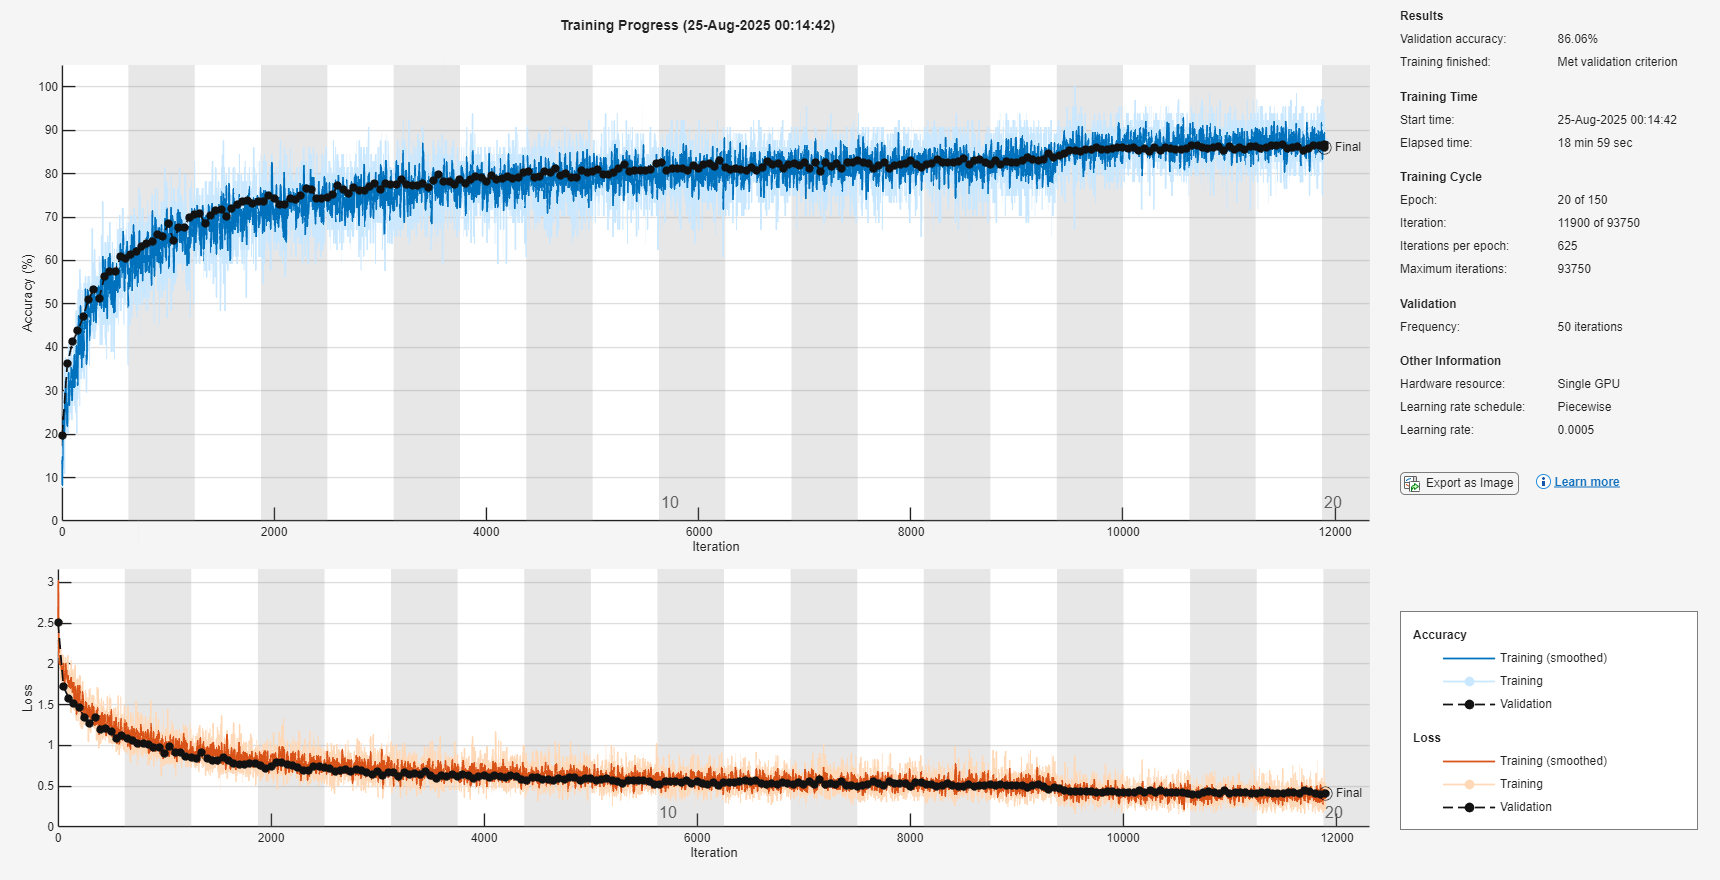


=== Done Training 27 ===


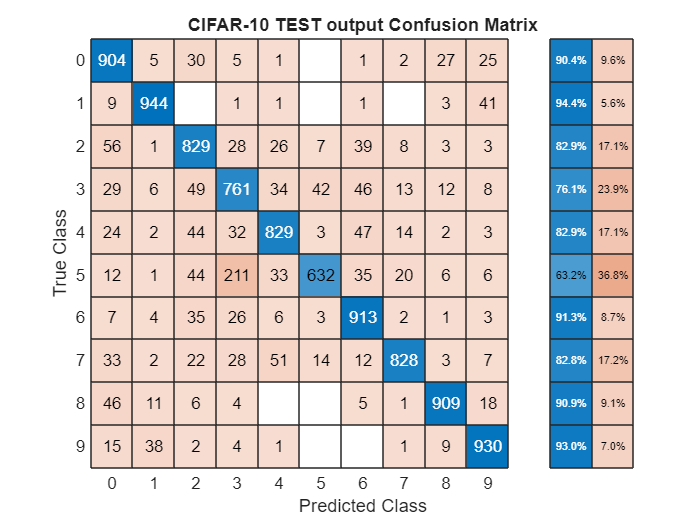

Overall Accuracy (from CM): 84.79%


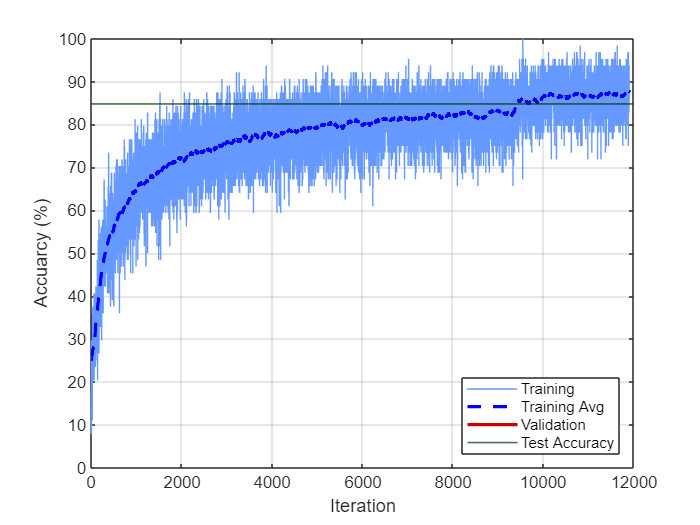

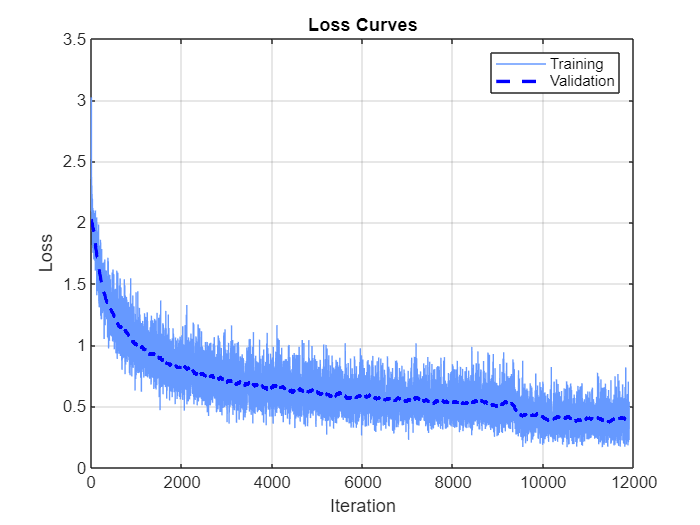

            runfile

            expNum = expNum + 1;
            %end
        end
    end
end